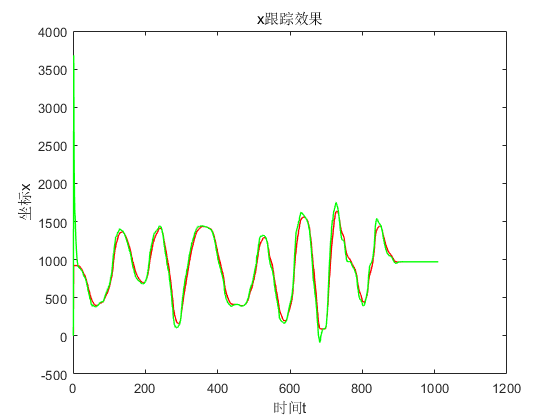

clc;clear all;

mouseOfposition=load('D:\Projects\Kalman_test\Kalman_test\positionVelocity_mouseOfPosition.txt');
predictOfposition=load('D:\Projects\Kalman_test\Kalman_test\positionVelocity_predictOfPosition.txt');

mouseOfVelocity=load('D:\Projects\Kalman_test\Kalman_test\positionVelocity_mouseOfVelocity.txt');
predictOfVelocity=load('D:\Projects\Kalman_test\Kalman_test\positionVelocity_predictOfVelocity.txt');

%位置
mouse_x=mouseOfposition(:,1);
mouse_y=mouseOfposition(:,2);
predict_x=predictOfposition(:,1);
predict_y=predictOfposition(:,2);

%速度
mouse_xOfv = mouseOfVelocity(:,1);
mouse_yOfv = mouseOfVelocity(:,2);
predict_xOfv=predictOfVelocity(:,1);
predict_yOfv=predictOfVelocity(:,2);

t=1:1:size(mouse_x);

figure(1);
plot(t,mouse_x,'r','LineWidth',1);
hold on;
plot(t,predict_x,'g','LineWidth',1);
title('x跟踪效果');
xlabel('时间t');
ylabel('坐标x')

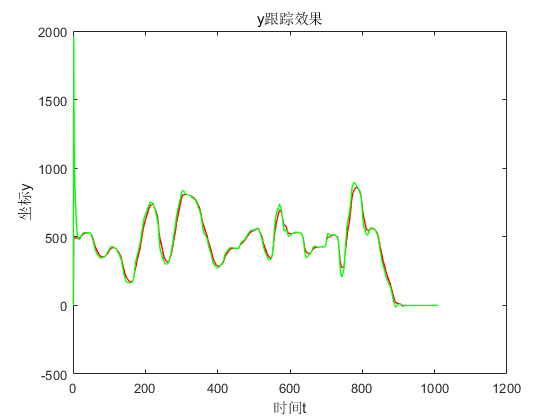


figure(2);
plot(t,mouse_y,'r','LineWidth',1);
hold on;
plot(t,predict_y,'g','LineWidth',1);
title('y跟踪效果');
xlabel('时间t');
ylabel('坐标y')

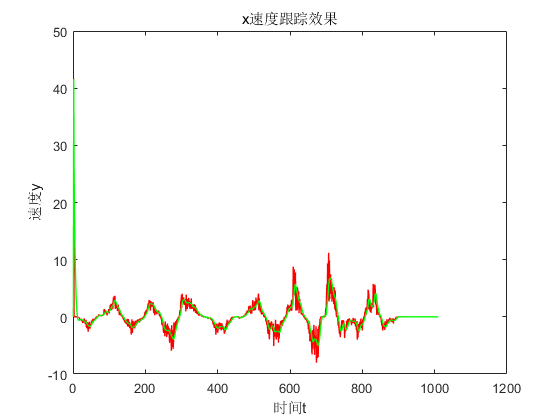


figure(3);
plot(t,mouse_xOfv,'r','LineWidth',1);
hold on;
plot(t,predict_xOfv,'g','LineWidth',1);
title('x速度跟踪效果');
xlabel('时间t');
ylabel('速度y')

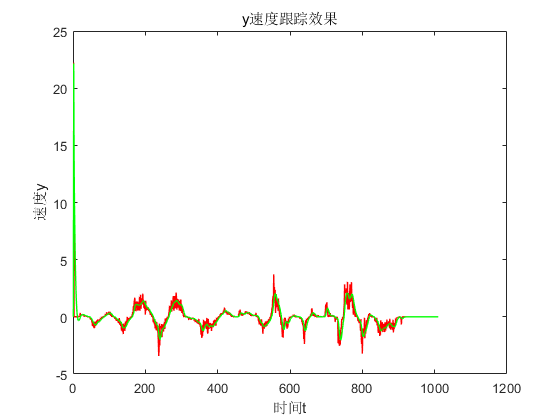


figure(4);
plot(t,mouse_yOfv,'r','LineWidth',1);
hold on;
plot(t,predict_yOfv,'g','LineWidth',1);
title('y速度跟踪效果');
xlabel('时间t');
ylabel('速度y')